# `Ch5_6_2`

# 用双线性变换法设计数字巴特沃斯滤波器

要求其指标为：

在$0\ldotp 2\pi \le \omega$的通带范围内幅度特性变化（下降) 小于 1 dB

在$0\ldotp 3\pi \le \omega \le \pi$的阻带范围内，衰减大于15 dB

实现上述滤波器

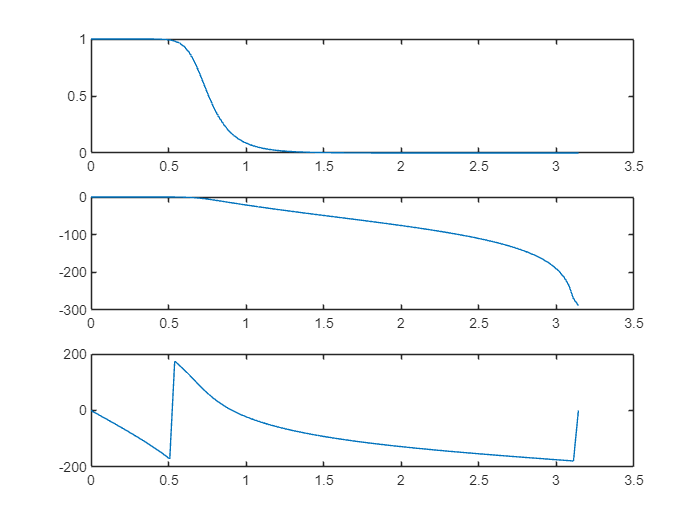

T = 1;
fs = 1;
Wp = 0.2*pi; % 数字频率
Ws = 0.3*pi; % 数字频率
Ap = 1; %dB
As = 15; %dB
wp = Wp/T; % 模拟角频率
ws = Ws/T; % 模拟角频率
fp = wp/(2*pi); %Hz 模拟频率
fst = ws/(2*pi); %Hz 模拟频率
% 预畸：
wp = 2/T*tan(Wp/2); % 预畸 模拟角频率
ws = 2/T*tan(Ws/2); % 预畸 模拟角频率
% 求N，wc：
[N,wc] = buttord_z(wp,ws,Ap,As,'s'); 
%设计模拟原型滤波器。
[Bs,As] = butter(N,wc,'s'); 
% 采用双线性变换法设计：
[Dz,Cz] = bilinear(Bs,As,fs);
Hz = filt(Dz,Cz);
% 画幅频、相频图：
figure;
W = linspace(0,pi); 
H = freqz(Dz,Cz,W);
mag = abs(H)/abs(H(1));
dbmag = 20*log10(mag);
phase = angle(H); %输出scale:-pi~pi
degphase = phase*180/pi; %转为degree
subplot(3,1,1), plot(W,abs(H));
subplot(3,1,2), plot(W,dbmag);
subplot(3,1,3), plot(W,degphase);